# 5. Improving Network Performance

#   5.2. Training Option

## Load Dataset

load ("Dataset_reshaped.mat")

## Spliting Data

Spliting training data into training and validation sets. (8:2)

pt = cvpartition(train_y,"HoldOut",0.2)

pt = 홀드아웃 교차 검증 분할
   NumObservations: 4000
       NumTestSets: 1
         TrainSize: 3200
          TestSize: 800
          IsCustom: 0


training_x = train_x(:,:,:,pt.training);
training_y = train_y(pt.training);

val_x = train_x(:,:,:,pt.test);
val_y = train_y(pt.test);



## Creating Network

Create a Convolutional Neural Network.

layers = [imageInputLayer([28,28,1]); convolution2dLayer([3,3],20);,...
    reluLayer(); maxPooling2dLayer([3,3]);...
    fullyConnectedLayer(10); softmaxLayer();]

layers =   다음 계층을 포함한 6×1 Layer 배열:

     1   ''   영상 입력          28×28×1 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      20개 3×3 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     3   ''   ReLU             ReLU
     4   ''   2차원 최댓값 풀링   3×3 최댓값 풀링 (스트라이드: [1  1], 채우기: [0  0  0  0])
     5   ''   완전 연결          10 완전 연결 계층
     6   ''   소프트맥스         소프트맥스

## Training Network

Create appropriate training options and train the network

opts = trainingOptions("sgdm","MaxEpochs",200,"InitialLearnRate",0.1,...
    "Plots","training-progress","Metrics","accuracy",...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",10,"LearnRateDropFactor",0.1,...
    "L2Regularization",0.1,...
    "ValidationData",{val_x,val_y})

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 50
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[28×28×1×800 double]  [800×1 categorical]}
             ValidationFrequency: [50]
              ValidationPatience: [Inf]
             ObjectiveMetricNa

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00          0.1                            2.2896                                     12.25
            1        1       00:00:00          0.1          2.2734                                16.406                      
           50        2       00:00:03          0.1         0.52367           0.59133              78.906                79.125
          100        4       00:00:05          0.1          0.3297           0.42666              88.281                85.125
          150        6       00:00:06          0.1         0.26325            0.4371              91.406                85.625
          200        8       00:00:07          0.1         0.26798           0.48626              89.062       

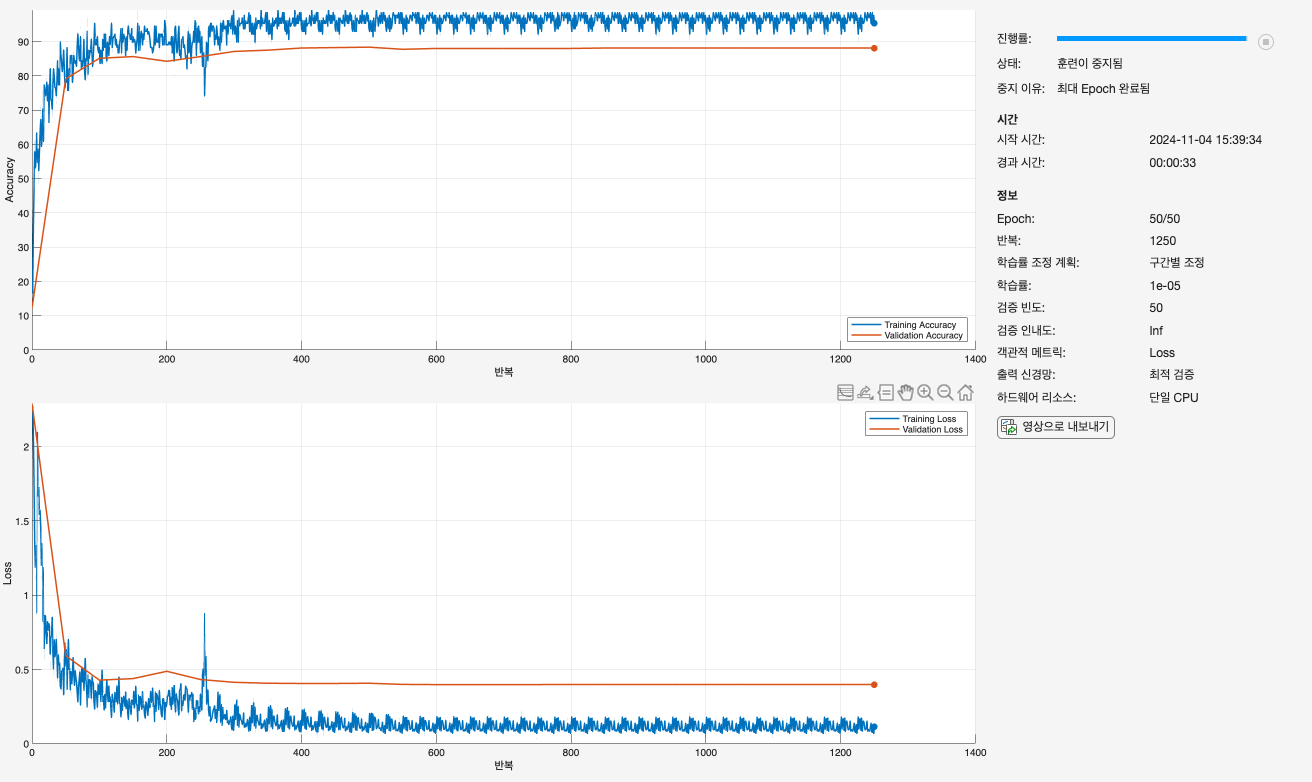


landnet = trainnet(training_x,training_y,layers,"crossentropy",opts);

## Evaluating Network

Calculate the prediction accuracy on the test data.

scores = minibatchpredict(landnet,test_x)

scores = 1000×10 single 행렬
    0.9772    0.0000    0.0005    0.0026    0.0000    0.0000    0.0196    0.0000    0.0000    0.0000
    0.0007    0.0000    0.4703    0.0000    0.0023    0.0000    0.5145    0.0000    0.0122    0.0001
    0.0767    0.0000    0.1431    0.0000    0.0000    0.0000    0.7798    0.0000    0.0004    0.0000
    0.8101    0.0005    0.0008    0.0017    0.1821    0.0000    0.0048    0.0000    0.0001    0.0000
    0.0028    0.0000    0.0008    0.0009    0.0000    0.0000    0.9954    0.0000    0.0001    0.0000
    0.9997    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000
    0.9300    0.0000    0.0006    0.0000    0.0000    0.0000    0.0687    0.0000    0.0006    0.0000
    0.2105    0.0038    0.0031    0.0575    0.0195    0.0000    0.6988    0.0004    0.0064    0.0000
    0.2507    0.0001    0.0006    0.2090    0.0518    0.0000    0.4858    0.0000    0.0021    0.0000
    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    

[testPred,score] = scores2label(scores,categories(training_y))

testPred = 1000×1 categorical 배열
     0 
     6 
     6 
     0 
     6 
     0 
     0 
     6 
     6 
     0 
     6 
     0 
     6 
     0 
     0 
     2 
     0 
     0 
     0 
     0 
     6 
     0 
     6 
     0 
     0 
     0 
     0 
     0 
     0 
     6 


score = 1000×1 single 열 벡터
    0.9772
    0.5145
    0.7798
    0.8101
    0.9954
    0.9997
    0.9300
    0.6988
    0.4858
    0.9999


testGT = test_y

testGT = 1000×1 categorical 배열
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


testAcc = nnz(testPred == testGT) / numel(testPred)

testAcc = 0.8790

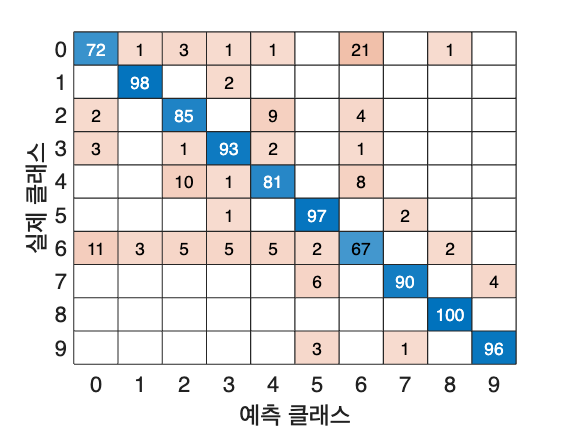

confusionchart(test_y,testPred)